%% 10번 문제
clear; clc;

rng('default');
num_days = 10000;
base_power = 500;

% (a) 
server_variance = 35 * randn(num_days, 1);

% (b) 
cooling_overload = rand(num_days, 1) <= 0.12;

% (c).
% 기본 사용량(500) + 서버 부하 변동 + 과부하인 날 추가 전력(120)
total_power = base_power + server_variance + (cooling_overload * 120);

% (d) 
over_650_ratio = mean(total_power > 650);
fprintf('=== 10번 결과 ===\n');

=== 10번 결과 ===


fprintf('전력 사용량이 650을 초과하는 날의 비율: %.2f%%\n', over_650_ratio * 100);

전력 사용량이 650을 초과하는 날의 비율: 2.36%



% (e) 
mean_overload = mean(total_power(cooling_overload));
mean_normal = mean(total_power(~cooling_overload));

fprintf('과부하 발생일의 평균 전력 사용량: %.2f\n', mean_overload);

과부하 발생일의 평균 전력 사용량: 619.94


fprintf('과부하 비발생일의 평균 전력 사용량: %.2f\n', mean_normal);

과부하 비발생일의 평균 전력 사용량: 500.07


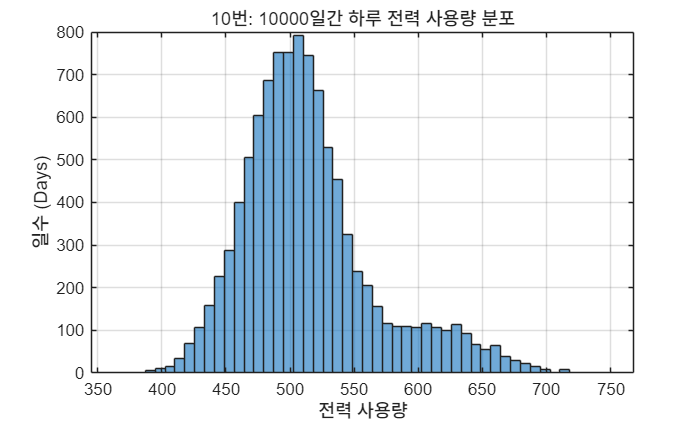


figure(11);
histogram(total_power, 50);
title('10번: 10000일간 하루 전력 사용량 분포');
xlabel('전력 사용량');
ylabel('일수 (Days)');
grid on;